**Apartado a)**

clear
syms K s
G=1/((s+1)*(s+2-j)*(s+2+j));

Calculamos los puntos de dispersión y confluencia.

K=-1/G;
dK=diff(K,s);
PtosDisp_Conf=solve(dK,s)

$$PtosDisp\_Conf = \left(\begin{array}{c} -\frac{5}{3}-\frac{\sqrt{2}\,\mathrm{i}}{3}\\ -\frac{5}{3}+\frac{\sqrt{2}\,\mathrm{i}}{3} \end{array}\right)$$

Calculamos los valores de K en los puntos de dispersión y confluencia.

k=double(subs(K,s,PtosDisp_Conf))

k =    0.7407 + 0.2095i
   0.7407 - 0.2095i


Comprobamos que |KG(s)|=1 en los puntos de dispersión y confluencia. 

Comprobacion=abs(subs(K,s,PtosDisp_Conf).*subs(G,s,PtosDisp_Conf))

$$Comprobacion = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

Estos puntos corresponden a los mejores valores que puede tomar K porque generan una salida que se aproxima a ser críticamente amortiguada (Se puede apreciar en la siguiente gráfica):

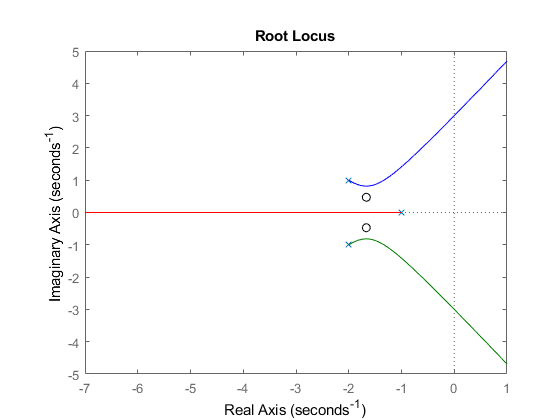

[n, d]=numden(G);
Fdt=tf(sym2poly(n),sym2poly(d));
rlocus(Fdt);
hold on;
scatter(real(PtosDisp_Conf),imag(PtosDisp_Conf),'black')
hold off;

Cálculo de estabilidad:

clear K;
syms K;
chareq = simplify(expand(1+K*G))==0;

Visualización de los coeficientes para la matriz.

cheq = simplify(chareq)

$$cheq = K\neq 0\wedge s^{3}+5\,s^{2}+9\,s+K=-5$$

RT=[1 5;
    9 K+5];
b1 = (RT(2,1)*RT(1,2)-RT(1,1)*RT(2,2))/RT(2,1);
b2 = (RT(2,1)*0-RT(1,1)*0)/RT(2,1);
c1 = (b1*RT(2,2)-RT(2,1)*b2)/b1;
c2 = (b1*0-RT(2,1)*0)/b1;

Matriz de Routh-Hurwitz

RT = [1 5;
      9 K+5;
      simplify(b1) b2;
      simplify(c1) c2]

$$RT = \left(\begin{array}{cc} 1 & 5\\ 9 & K+5\\ \frac{40}{9}-\frac{K}{9} & 0\\ K+5 & 0 \end{array}\right)$$

K1 = vpasolve(b1, K)

$$K1 = 40.0$$

K2 = vpasolve(c1, K)

$$K2 = -5.0$$

Para que el output de la FdT sea estable, K debe comprender valores entre -5 y 40, no inclusivo.

Comprobación gráfica de estabilidad:

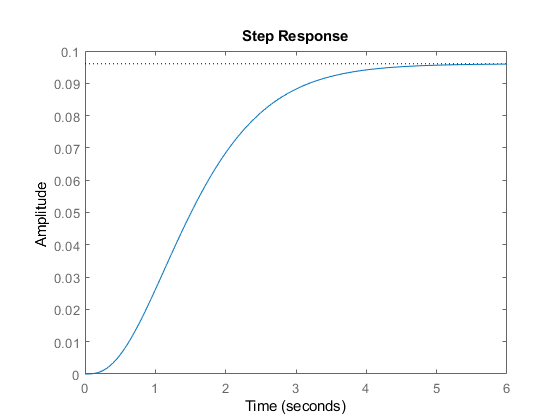

K=real(k(2))+imag(k(2));
M=K*G/(1+K*G);
[n, d]=numden(eval(M));
Fdt=tf(sym2poly(n),sym2poly(d));
step(Fdt);

**Apartado b)**

clear
syms K s
G=(s+1)/(s^2*(s+9));

Calculamos los puntos de dispersión y confluencia.

K=-1/G;
dK=diff(K,s);
PtosDisp_Conf=solve(dK,s)

$$PtosDisp\_Conf = \left(\begin{array}{c} -3\\ 0 \end{array}\right)$$

Calculamos los valores de K en los puntos de dispersión y confluencia.

k=double(subs(K,s,PtosDisp_Conf))

k =     27
     0


Comprobamos que |KG(s)|=1 en los puntos de dispersión y confluencia. 

Comprobacion=abs(subs(K,s,PtosDisp_Conf(1)).*subs(G,s,PtosDisp_Conf(1)))

$$Comprobacion = 1$$

Como veremos a continuación, los puntos de dispersión y confluencia calculados representan fielmente el resultado esperado pues, cuando s=-3, se produce una confluencia y una dispersión, y cuando s=0, se produce una dispersión. Los valores de K para estos puntos generan un output críticamente amortiguado.

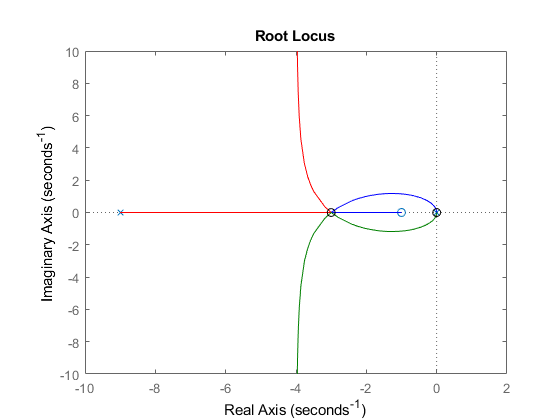

[n, d]=numden(G);
Fdt=tf(sym2poly(n),sym2poly(d));
rlocus(Fdt);
hold on;
scatter(real(PtosDisp_Conf),imag(PtosDisp_Conf),'black')
hold off;

Cálculo de estabilidad:

clear K;
syms K;
chareq = simplify(expand(1+K*G))==0;

Visualización de los coeficientes para la matriz.

cheq = simplify(chareq)

$$cheq = s^{3}+9\,s^{2}+K\,s+K=0$$

RT=[1 9;
    K K];
b1 = (RT(2,1)*RT(1,2)-RT(1,1)*RT(2,2))/RT(2,1);
b2 = (RT(2,1)*0-RT(1,1)*0)/RT(2,1);
c1 = (b1*RT(2,2)-RT(2,1)*b2)/b1;
c2 = (b1*0-RT(2,1)*0)/b1;

Matriz de Routh-Hurwitz

RT = [1 9;
      K K;
      simplify(b1) b2;
      simplify(c1) c2]

$$RT = \left(\begin{array}{cc} 1 & 9\\ K & K\\ 8 & 0\\ K & 0 \end{array}\right)$$

K1 = vpasolve(c1, K)

$$K1 = 0$$

Para que el output de la FdT sea estable, K debe ser mayor que 0.

Comprobación gráfica de estabilidad:

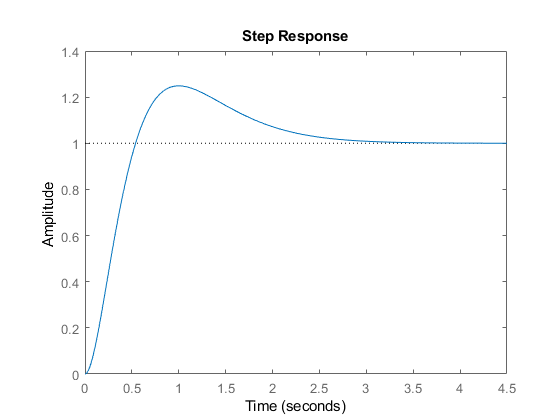

K=k(1);
M=K*G/(1+K*G);
[n, d]=numden(eval(M));
Fdt=tf(sym2poly(n),sym2poly(d));
step(Fdt);

**Apartado c)** 

clear
syms K s
G=(s+2) / (s^2+3*s+5);

Calculamos los puntos de dispersión y confluencia.

K=-1/G;
dK=diff(K,s);
PtosDisp_Conf=solve(dK,s)

$$PtosDisp\_Conf = \left(\begin{array}{c} -\sqrt{3}-2\\ \sqrt{3}-2 \end{array}\right)$$

Descartamos el segundo valor de s. Calculamos K en el punto de dispersión y confluencia.

k=double(subs(K,s,PtosDisp_Conf(1)))

k = 4.4641

Comprobamos que |KG(s)|=1 en los puntos de dispersión y confluencia. 

Comprobacion=abs(subs(K,s,PtosDisp_Conf(1)).*subs(G,s,PtosDisp_Conf(1)))

$$Comprobacion = 1$$

Este punto corresponde al mejor valor que puede tomar K porque genera una salida críticamente amortiguada (Se puede apreciar en la siguiente gráfica):

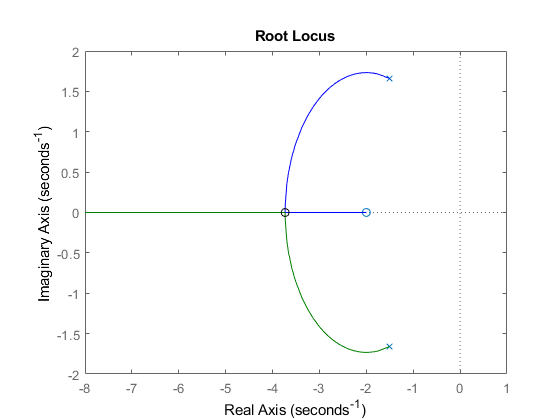

[n, d]=numden(G);
Fdt=tf(sym2poly(n),sym2poly(d));
rlocus(Fdt);
hold on;
scatter(real(PtosDisp_Conf(1)),imag(PtosDisp_Conf(1)),'black')
hold off;

Como podemos apreciar, la dispersión y confluencia se dan en el mismo punto.

Cálculo de estabilidad:

clear K;
syms K;
chareq = simplify(expand(1+K*G))==0;

Visualización de los coeficientes para la matriz.

cheq = simplify(chareq)

$$cheq = 2\,K+3\,s+K\,s+s^{2}=-5$$

RT=[1 5+2*K;
    3+K 0];
b1 = (RT(2,1)*RT(1,2)-RT(1,1)*RT(2,2))/RT(2,1);
b2 = (RT(2,1)*0-RT(1,1)*0)/RT(2,1);

Matriz de Routh-Hurwitz

RT = [1 5+2*K;
        3+K 0;
      simplify(b1) b2;]

$$RT = \left(\begin{array}{cc} 1 & 2\,K+5\\ K+3 & 0\\ 2\,K+5 & 0 \end{array}\right)$$

K1 = vpasolve(b1, K)

$$K1 = -2.5$$

Para que el output de la FdT sea estable, K debe ser mayor que -2.5.

Comprobación gráfica de estabilidad:

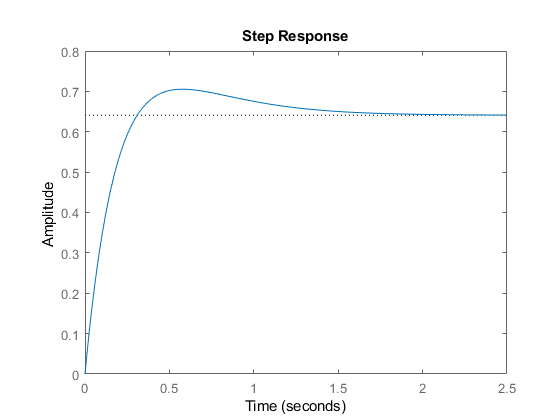

K=k;
M=K*G/(1+K*G);
[n, d]=numden(eval(M));
Fdt=tf(sym2poly(n),sym2poly(d));
step(Fdt);